Labo A - Principes van digitale signaalverwerking

2.4 Datasets:

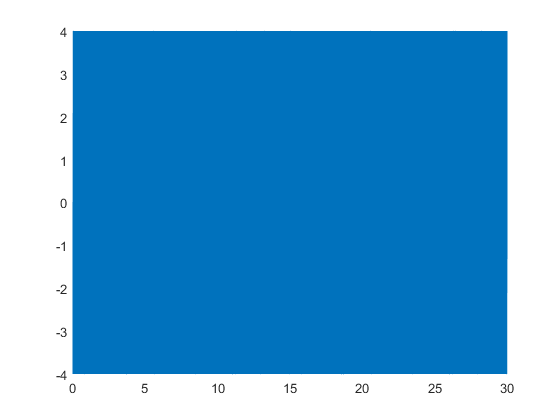

r = 4;
f = 440;
fs = 8192;
Ts = 1/fs;
t = (0:Ts:30);

a = r * sin(2 * pi * f * t);
plot(t, a)

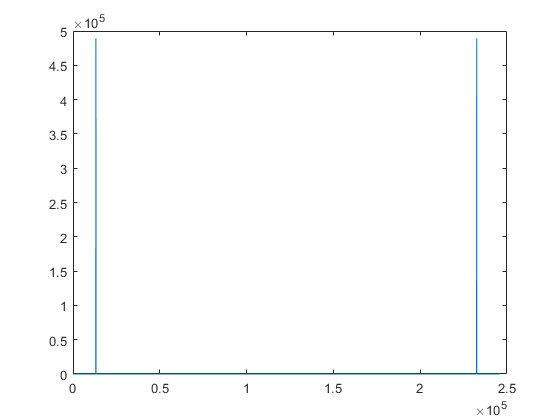

plot(abs(fft(a)))

b = load('handel')

b = struct with fields:
     y: [73113×1 double]
    Fs: 8192


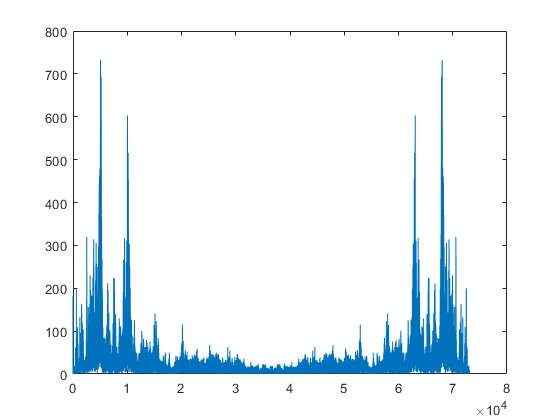

plot(abs(fft(b.y)))

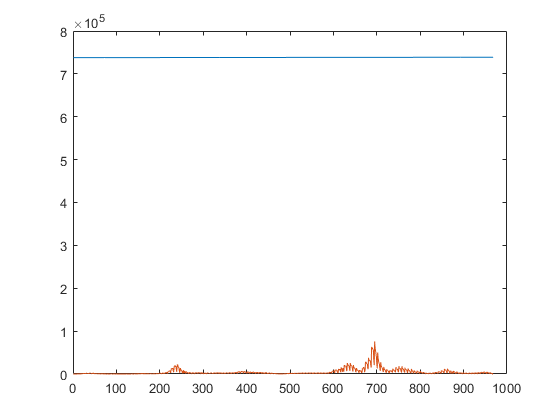

c = csvread("covid19(1).csv");
plot(c)

Sampling:

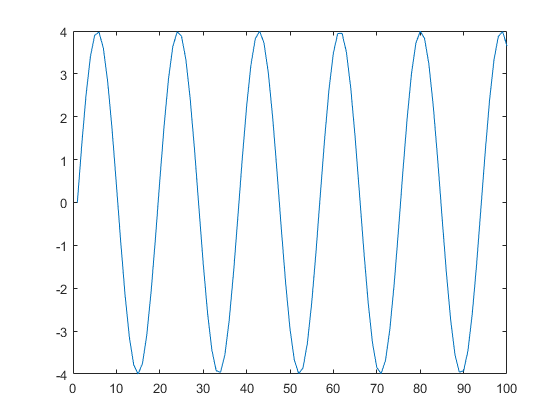

plot(a(1:100))

Discrete tijdsdomein eerste 100 samples:

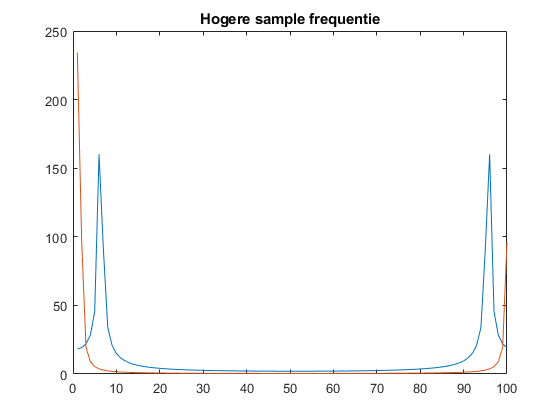

plot(abs(fft(a(1:100))))
title('Hogere sample frequentie')
hold on

fs = fs * 10;
Ts = 1/fs;
t = (0:Ts:30);
a = r * sin(2 * pi * f * t);
plot(abs(fft(a(1:100))))
hold off

We horen een zeer storend geluid...

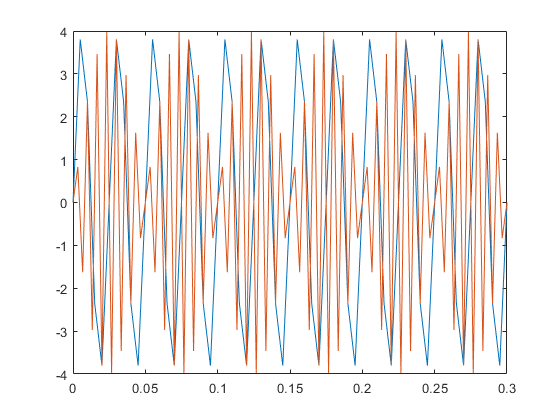

fs = 200;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

hold on

fs = 300;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

hold off

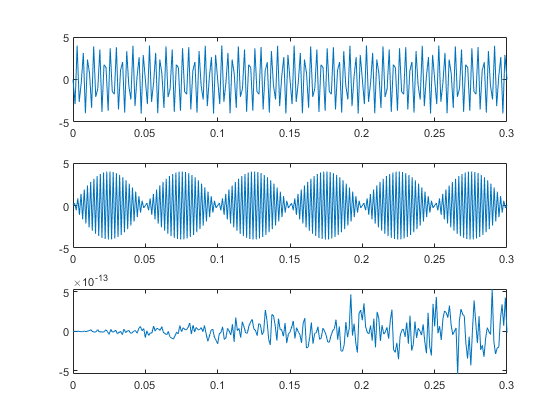

subplot(3, 1, 1);

fs = 700;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

subplot(3, 1, 2);
fs = 900;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

subplot(3, 1, 3);
fs = 880;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
plot(t, a)

Wanneer we deze samplefrequentie te laag nemen (onder de 2x de frequentie), dan is het stelsel van Nyquist niet tevreden en treed er aliasing op.

wanneer de sample frequentie exact gelijk is aan 2x de frequentie, dan krijgen we een lijn die (praktisch) nul is. Deze toont anders aan omdat de schaal zeer klein is en dit is denk ik doordat er enkele afrondingen gebeuren

Kwantisatie:

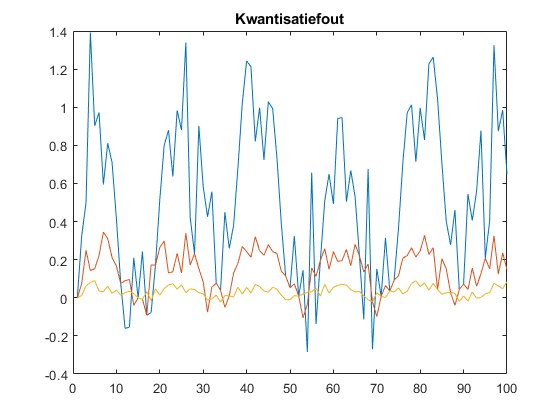

figure;

fs = 8192;
Ts = 1/fs;
t = (0:Ts:0.3);
a = r * sin(2 * pi * f * t);
a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 3) - 1) * a0;
a2 = round(a1);
a3 = a2 * (max(a) - min(a)) / (power(2, 3)) + min(a);

plot(a(1:100) - a3(1:100))
hold on

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 5) - 1) * a0;
a2 = round(a1);
a5 = a2 * (max(a) - min(a)) / (power(2, 5)) + min(a);

plot(a(1:100) - a5(1:100))
hold on

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 7) - 1) * a0;
a2 = round(a1);
a7 = a2 * (max(a) - min(a)) / (power(2, 7)) + min(a);

plot(a(1:100) - a7(1:100))
title('Kwantisatiefout');
hold off

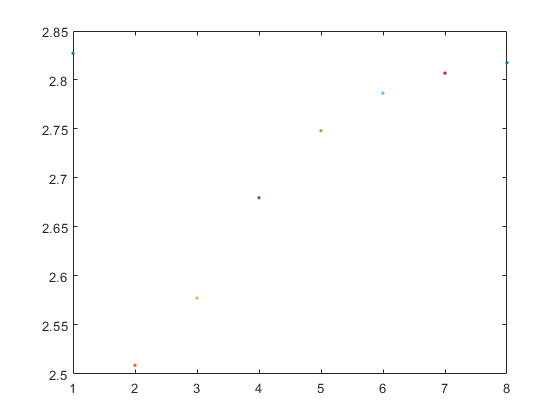

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 1) - 1) * a0;
a2 = round(a1);
b1 = a2 * (max(a) - min(a)) / (power(2, 1)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 2) - 1) * a0;
a2 = round(a1);
b2 = a2 * (max(a) - min(a)) / (power(2, 2)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 3) - 1) * a0;
a2 = round(a1);
b3 = a2 * (max(a) - min(a)) / (power(2, 3)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 4) - 1) * a0;
a2 = round(a1);
b4 = a2 * (max(a) - min(a)) / (power(2, 4)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 5) - 1) * a0;
a2 = round(a1);
b5 = a2 * (max(a) - min(a)) / (power(2, 5)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 6) - 1) * a0;
a2 = round(a1);
b6 = a2 * (max(a) - min(a)) / (power(2, 6)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 7) - 1) * a0;
a2 = round(a1);
b7 = a2 * (max(a) - min(a)) / (power(2, 7)) + min(a);

a0 = (a - min(a)) / (max(a) - min(a));
a1 = (power(2, 8) - 1) * a0;
a2 = round(a1);
b8 = a2 * (max(a) - min(a)) / (power(2, 8)) + min(a);

plot(1, rms(b1), '.')
hold on
plot(2, rms(b2), '.')
hold on
plot(3, rms(b3), '.')
hold on
plot(4, rms(b4), '.')
hold on
plot(5, rms(b5), '.')
hold on
plot(6, rms(b6), '.')
hold on
plot(7, rms(b7), '.')
hold on
plot(8, rms(b8), '.')
hold off